# Exergy Analysis Demo

Use `ExergyAnalysis` function to obtain the exergy balances and Table FP for one state of the plant

### Read the Data Model

file="C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\cgam\cgam_model.json";
data=ReadDataModel(file);

### Select the state of the plant to analyze

states=string(data.StateNames);
state=char(states(2));

### Get Exergy Analysis

Use function `ExergyAnalysis `to get the exergy balance for the selected state, and print de processes balance using function `ShowResults`

res=ExergyAnalysis(data,'State',state);
ShowResults(res,'Table','eprocesses');


Processes Exergy Table - T1180

Key          F(MW)       P(MW)       I(MW)       k(J/J)      η (%)
———————————————————————————————————————————————————————————————————
COMB       124.223     103.462      20.761       1.2007      83.29
CMP         32.033      29.507       2.526       1.0856      92.11
TRB         64.727      62.033       2.694       1.0434      95.84
APH         23.714      21.389       2.325       1.1087      90.20
HRSG        12.791       9.403       3.388       1.3603      73.52
STCK         2.230       2.230       0.000       1.0000     100.00
ENV         73.327      39.403      33.924       1.8609      53.74



### Show the Diagram FP

Show the Diagram FP as graph using `ShowGraph` function

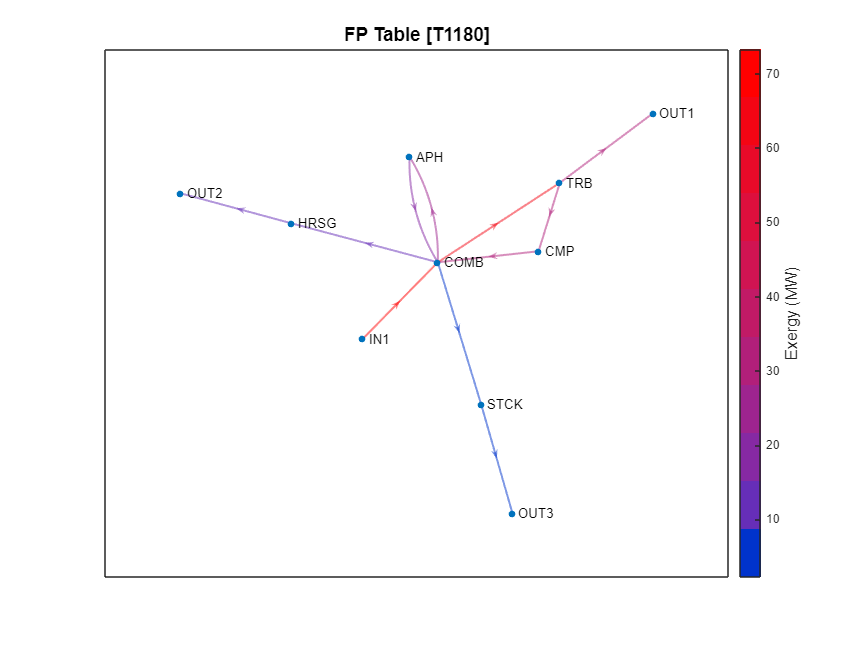

ShowGraph(res)

### Additional Help Information

help ExergyAnalysis

 ExergyAnalysis - Get the exergy analysis for a plant state.
    Given a data model of a plant, this function performs an exergy analysis,
    including the exergy balances and the Fuel-Product table.
  
    Syntax
      res = ExergyAnalysis(data,Name,Value)
  
    Input Arguments
      data - cReadModel object containing the data information
     
    Name-Value Arguments
      State - State name of the exergy data. If not provided, first state is used
        char array
      Show -  Show the results on console.  
        true | false (default)
      SaveAs - Name of file (with extension) to save the results.
        char array | string
  
    Output Arguments
      res - cResultsInfo object contains the results of the exergy analysis for the required state
     The following tables are obtained:
      eflows - exergy of the flows
      estreams - exergy of the streams
      eprocesses - exergy balance of the processes
      tfp - Exergy Fuel-Product